# Assignment 1 

s224507

## Read the rocorded signal

signal = audioread('ihhhh2.wav');
audioinfo('ihhhh2.wav')         

ans = struct with fields:
             Filename: '/Users/rosemariewodschow/Library/CloudStorage/OneDrive-DanmarksTekniskeUniversitet/5.Semester/Signaler og lineære systemer i diskret tid/Assignment1/Assignment1_s224507/ihhhh2.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 48000
         TotalSamples: 228352
             Duration: 4.7573
                Title: 'Ny optagelse 5'
              Comment: []
               Artist: []
        BitsPerSample: 16


## Figure 1

### Comaparison of Pure and Recorded signals in Time Domain

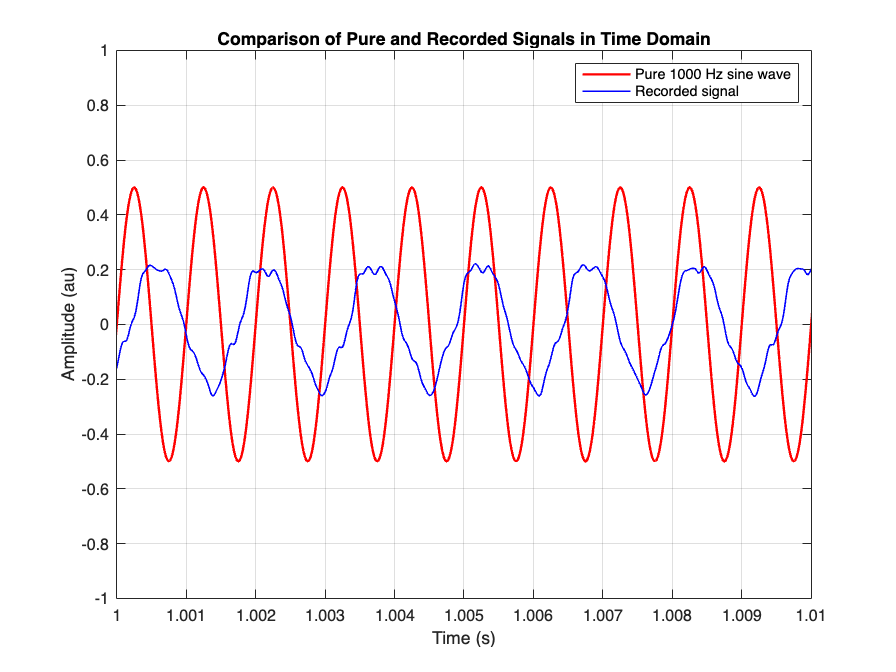

% Sample rate and duration and time-vector
fs = 48000;                        
duration = 4.7573;                  
t = 0:1/fs:duration-1/fs;           

% Generating pure signal
x1 = 0.5*sin(1000*2*pi*t);          

% Plotting the pure signal
plot(t, x1, 'r', 'LineWidth', 1.5)  
hold on                            

% Plot recorcorded signal
plot(t, signal(1:end-2), 'b', 'LineWidth', 1) % Plot recorded signal in blue
xlim([1, 1.01])                     


xlabel('Time (s)')
ylabel('Amplitude (au)')
title('Comparison of Pure and Recorded Signals in Time Domain')
legend('Pure 1000 Hz sine wave', 'Recorded signal')
grid on;
ylim([-1, 1])

hold off

## Figure 2

### Comparison of Pure and Recorded Signals in the Magnitude Spectrum

#### Fourier transform:

%% Fouriertransformationen of the recorded signal
fs = 48000;                         

% Taking the last 24000 samples from the signal
signal_section = signal(end-24000+1:end);       %24.000/48.000 = 0,5 secounds

% Duration and frequency resolution for the recorded signal
duration = length(signal_section)/fs;                    
delta_f = 1/duration;  
X = 2*abs(fft(signal_section))/length(signal_section);  
X = fftshift(X);  % Shift --> center the FFT around 0 Hz
freq = -fs/2:delta_f:fs/2-delta_f;


% Parameters for Pure sinusoidale signal
A = 1;           % Amplitude
f = 1000;        % Frequency i Hz
phi = 0;         % Phase
fs_sin = 48000;  % Sampling frequency 
T0 = 0.5;        % Duration in seconds

% Generate the pure signal using function
[x_values, y_values] = generate_sinusoid(A, f, phi, fs_sin, T0);

% Generating spectrum for the pure sinusoidal
Y = 2*abs(fft(y_values)/length(y_values));
Y = fftshift(Y);
freq_sin = linspace(-fs_sin/2, fs_sin/2, length(Y));


#### Plot:

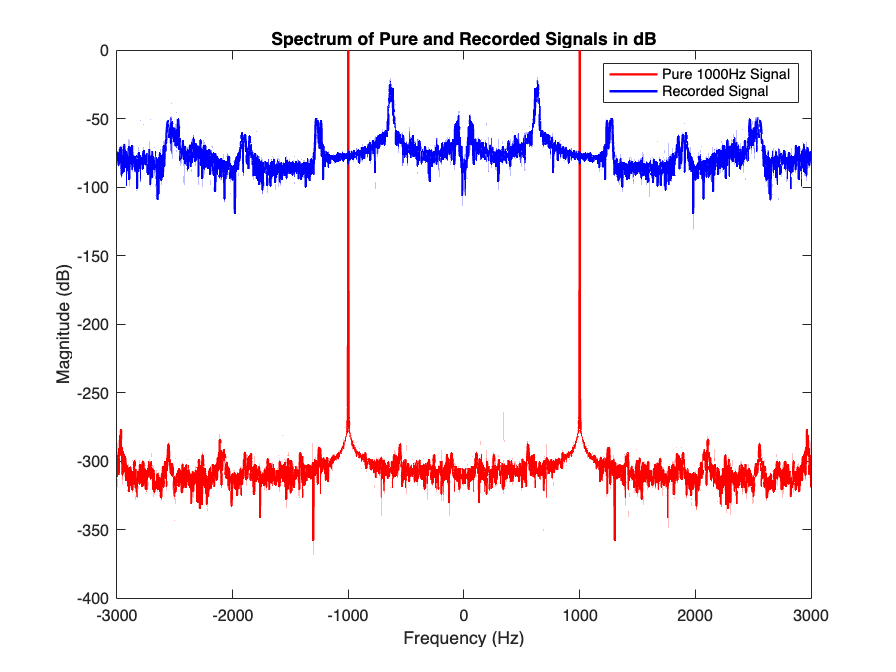

% Spectrum for the pure sinusoidal signal
figure;
if length(freq) ~= length(Y)  % Checking if vecrors are same length
    freq_pure = linspace(-fs_sin/2, fs_sin/2, length(Y));
else
    freq_pure = freq;
end

% Plot the pure sinusoidal
plot(freq_pure, 20*log10(abs(Y)), 'r', 'LineWidth', 1.5); 
hold on;

% Plot the spectrum for recorded signal
if length(freq) ~= length(X)
    freq_recorded = linspace(-fs/2, fs/2, length(X));
else
    freq_recorded = freq;
end

% Plot the recorded signal
plot(freq_recorded, 20*log10(abs(X)), 'b', 'LineWidth', 1.5);

% Setting cosmetics
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Spectrum of Pure and Recorded Signals in dB');
xlim([-3000 3000]);
legend('Pure 1000Hz Signal','Recorded Signal');

hold off;

### Extra Plot (stem-plot)

### Frequency resolution of the DFT schold be 2 Hz

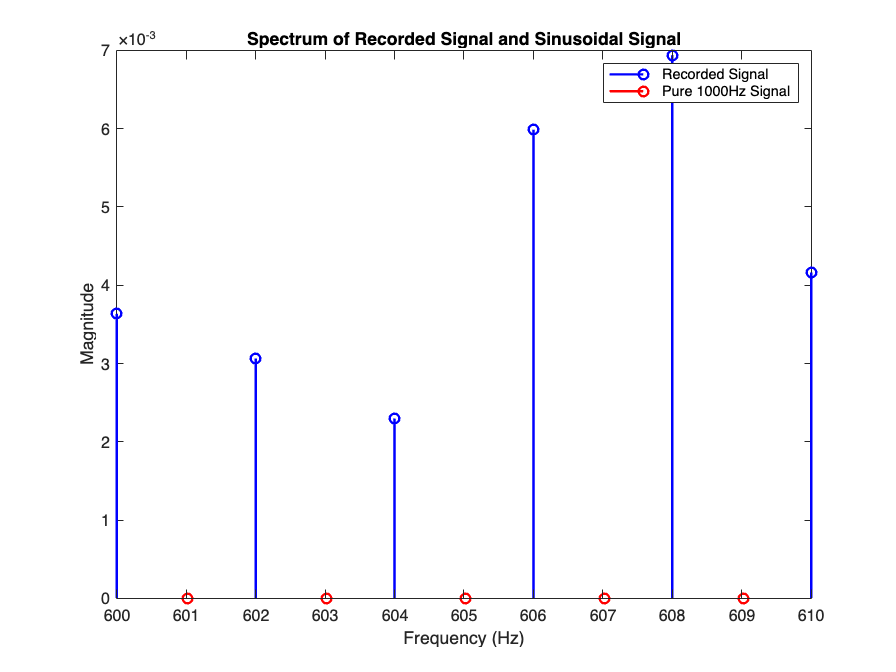

figure;

% Plotting the recorded signal spectrum
stem(freq, (abs(X)), 'b', 'LineWidth', 1.5);
hold on;

% Plotting the sinusoidal signal spectrum
stem(freq_sin, abs(Y), 'r', 'LineWidth', 1.5);

% Setting cosmetics
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Spectrum of Recorded Signal and Sinusoidal Signal');
legend('Recorded Signal', 'Pure 1000Hz Signal');
xlim([600 610]); %making small range to see the frequency resolution
ylim([0.00 0.007]);
hold off;

#### Generating a pure 1000Hz Sinusoid signal (function)


% Function: Generates Sinusoid (save as 'generate_sinusoid.m')
function [time_vector, signal] = generate_sinusoid(A, f, phi, fs, T_s)
    % Time vector
    time_vector = 0:1/fs:T_s-1/fs; 

    % The signal
    signal = A * cos(2 * pi * f * time_vector + phi * 2 * pi);
end

#### Generating a spectrum (function)

function [Y, freq] = make_spectrum(signal, fs)

    % Computing the FFT of the signal (complex-valued)
    Y = fft(signal);
    
    % Normalizing the FFT by the length of the signal
    Y = Y / length(Y);    

    % Frequency resolution
    N = length(signal);           % Number of samples
    T0 = N / fs;                  % Duration of signal in seconds
    delta_f = 1 / T0;             % Frequency resolution

    % Frequency vector (positive and negative frequencies)
    if mod(N, 2) == 0
        % FOR EVEN NUMBER OF SAMPLES
        f_pos = 0:delta_f:fs/2;    % Positive frequencies up to fs/2
        f_neg = -fs/2+delta_f:delta_f:-delta_f; % Negative frequencies
    else
        % FOR ODD NUMBER OF SAMPLES
        f_pos = 0:delta_f:(floor(N/2) * delta_f); % Up to just below Nyquist
        f_neg = -(floor(N/2)) * delta_f:delta_f:-delta_f; % Negative frequencies
    end

    % Combine positive and negative frequencies
    freq = [f_pos f_neg];


    % Convert to column vectors if necessary
    Y = Y(:);
    freq = freq(:);
end

